ECoG_data = load("ECoG.mat");
Motion_data = load("Motion.mat")

Motion_data = struct with fields:
            Fsm: 50
     Left_Wrist: [51293x3 double]
    Motion_time: [51293x1 double]
    Right_Wrist: [51293x3 double]


ECoG_data

ECoG_data = struct with fields:
         ECoG: [1024398x64 double]
    ECoG_time: [1024398x1 double]
           Fs: 1000


Motion_data

Motion_data = struct with fields:
            Fsm: 50
     Left_Wrist: [51293x3 double]
    Motion_time: [51293x1 double]
    Right_Wrist: [51293x3 double]


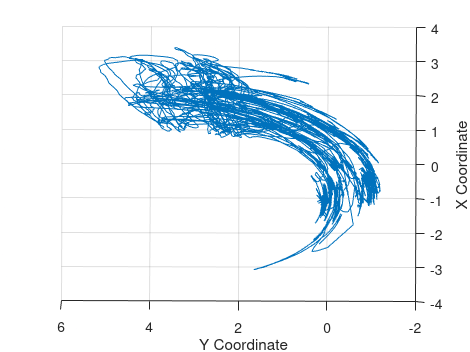

figure;
title("Bilateral Motion Data, Session 1, Right Wrist");
plot3(Motion_data.Right_Wrist(:,1), Motion_data.Right_Wrist(:,2), Motion_data.Right_Wrist(:,3))
xlabel("X Coordinate");
ylabel("Y Coordinate");
zlabel("Z Coordinate");
grid("on")

view([-89.72 90.00])

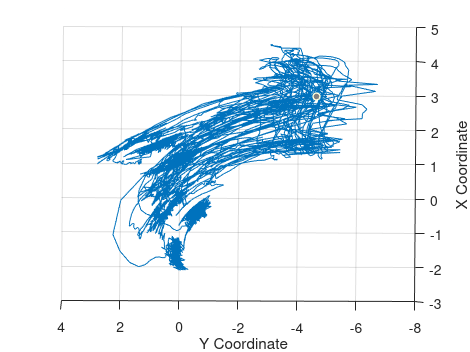

figure;
title("Bilateral Motion Data, Session 1, Right Wrist");
plot3(Motion_data.Left_Wrist(:,1),Motion_data.Left_Wrist(:,2),Motion_data.Left_Wrist(:,3))
xlabel("X Coordinate")
ylabel("Y Coordinate")
zlabel("Z Coordinate")
grid("on")

view([-89.65 90.00])

size(ECoG_data.ECoG)

ans =      1024398          64


ECoG_data.ECoG(:, 1) % Channel 1 data

ans = 1.0e+03 *

    0.5484
    0.4694
    0.3219
    0.2689
   -0.0232
    0.0336
   -0.1682
   -0.1820
   -0.1862
   -0.0816


ECoG_data.ECoG(:, 1)

ans = 1.0e+03 *

    0.5484
    0.4694
    0.3219
    0.2689
   -0.0232
    0.0336
   -0.1682
   -0.1820
   -0.1862
   -0.0816


% Assume your matrix is named 'data'
% Plot first 3 channels
time = ECoG_data.ECoG_time

time = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


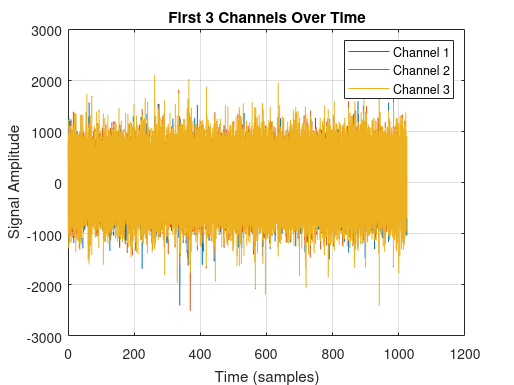

figure;
plot(time, ECoG_data.ECoG(:, (1:3)));
legend('Channel 1', 'Channel 2', 'Channel 3');
xlabel('Time (samples)');
ylabel('Signal Amplitude');
title('First 3 Channels Over Time');
grid on;

% Assume your matrix is named 'data'
% Plot first 3 channels
time = ECoG_data.ECoG_time

time = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


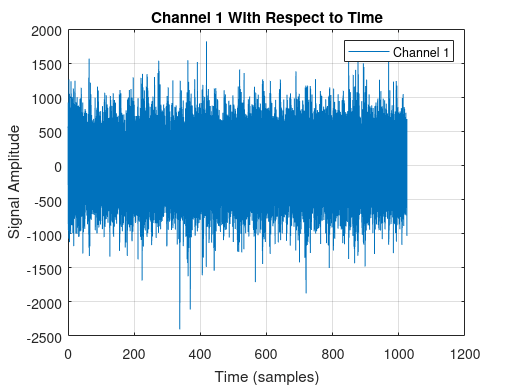

figure;
plot(time, ECoG_data.ECoG(:, (1)));
legend('Channel 1');
xlabel('Time (samples)');
ylabel('Signal Amplitude');
title('Channel 1 With Respect to Time');
grid on;